# Season 3: Controllability, Observability, and Realization

**Learning Outcomes:**

- Test controllability and observability using rank and PBH criteria

- Understand and compute controllability/observability gramians

- Perform Kalman decomposition to identify structural properties

- Transform systems to canonical forms

- Compute minimal realizations

- Apply balanced realization for model reduction

**Prerequisites:** Season 1 & 2 (Mathematical Foundations, State-Space Modeling)

**MATLAB Version:** R2025b

**Toolboxes Required:** Control System Toolbox, Symbolic Math Toolbox

close all; clear; clc;
rng(0);

## Section 3.1: Controllability - Rank Test

**Mathematical Background**

A system (A,B) is controllable if the **controllability matrix** has full rank:


$$\mathcal{C} = [B\ AB\ A^2B\ \ldots\ A^{n-1}B]$$


rank(C) = n ⟺ system is controllable

**Physical Meaning:** Can reach any state from any initial state using input u(t)

Example 1: Fully controllable system

A1 = [0 1; -2 -3];
B1 = [0; 1];

fprintf('Example 1: Second-order system\n');

Example 1: Second-order system


fprintf('A =\n'); disp(A1);

A =
     0     1
    -2    -3



fprintf('B =\n'); disp(B1);

B =
     0
     1




% Compute controllability matrix
C_ctrb1 = ctrb(A1, B1);
rank_c1 = rank(C_ctrb1);
n1 = size(A1, 1);

fprintf('Controllability matrix C = [B AB]:\n');

Controllability matrix C = [B AB]:


disp(C_ctrb1);

     0     1
     1    -3



fprintf('Rank: %d, System order: %d\n', rank_c1, n1);

Rank: 2, System order: 2



if rank_c1 == n1
    fprintf('✓ System is CONTROLLABLE\n\n');
else
    fprintf('✗ System is NOT controllable\n\n');
end

✓ System is CONTROLLABLE



Example 2: Uncontrollable system

A2 = [1 1; 4 -2];
B2 = [0; 0];

fprintf('Example 2: Uncontrollable system\n');

Example 2: Uncontrollable system


fprintf('A =\n'); disp(A2);

A =
     1     1
     4    -2



fprintf('B =\n'); disp(B2);

B =
     0
     0




C_ctrb2 = ctrb(A2, B2);
rank_c2 = rank(C_ctrb2);
n2 = size(A2, 1);

fprintf('Controllability matrix C = [B AB]:\n');

Controllability matrix C = [B AB]:


disp(C_ctrb2);

     0     0
     0     0



fprintf('Rank: %d, System order: %d\n', rank_c2, n2);

Rank: 0, System order: 2



if rank_c2 == n2
    fprintf('✓ System is CONTROLLABLE\n\n');
else
    fprintf('✗ System is NOT controllable (rank deficiency: %d)\n\n', n2 - rank_c2);
end

✗ System is NOT controllable (rank deficiency: 2)



Example 3: Multi-input system

A3 = [0 1 0; 0 0 1; -1 -2 -3];
B3 = [0 1; 0 0; 1 0];

fprintf('Example 3: Multi-input system (3 states, 2 inputs)\n');

Example 3: Multi-input system (3 states, 2 inputs)


fprintf('A =\n'); disp(A3);

A =
     0     1     0
     0     0     1
    -1    -2    -3



fprintf('B =\n'); disp(B3);

B =
     0     1
     0     0
     1     0




C_ctrb3 = ctrb(A3, B3);
rank_c3 = rank(C_ctrb3);
n3 = size(A3, 1);

fprintf('Controllability matrix C = [B AB]:\n');disp(C_ctrb3);

Controllability matrix C = [B AB]:
     0     1     0     0     1     0
     0     0     1     0    -3    -1
     1     0    -3    -1     7     3



fprintf('Controllability matrix size: %dx%d\n', size(C_ctrb3, 1), size(C_ctrb3, 2));

Controllability matrix size: 3x6


fprintf('Rank: %d, System order: %d\n', rank_c3, n3);

Rank: 3, System order: 3



if rank_c3 == n3
    fprintf('✓ System is CONTROLLABLE\n\n');
else
    fprintf('✗ System is NOT controllable\n\n');
end

✓ System is CONTROLLABLE



## Section 3.2: Observability - Rank Test

**Mathematical Background**

A system (A,C) is observable if the observability matrix has full rank:


$$O=\left\lbrack \begin{array}{c}
C\\
\textrm{CA}\\
\vdots \\
{\textrm{CA}}^{N-1} 
\end{array}\right\rbrack$$


rank(O) = n ⟺ system is observable

**Physical Meaning:** Can determine initial state from output measurements

Example 1: Fully observable system

C1 = [1 0];  % Measure first state

fprintf('Example 1: Measure first state only\n');

Example 1: Measure first state only


fprintf('A =\n'); disp(A1);

A =
     0     1
    -2    -3



fprintf('C =\n'); disp(C1);

C =
     1     0




O_obsv1 = obsv(A1, C1);
rank_o1 = rank(O_obsv1);

fprintf('Observability matrix O = [C; CA]:\n');

Observability matrix O = [C; CA]:


disp(O_obsv1);

     1     0
     0     1



fprintf('Rank: %d, System order: %d\n', rank_o1, n1);

Rank: 2, System order: 2



if rank_o1 == n1
    fprintf('✓ System is OBSERVABLE\n\n');
else
    fprintf('✗ System is NOT observable\n\n');
end

✓ System is OBSERVABLE



Example 2: Unobservable system

A4 = [1 1; 4 -2];
C4 = [-1 1; 1 -1];  % Both rows are linearly dependent

fprintf('Example 2: Linearly dependent output measurements\n');

Example 2: Linearly dependent output measurements


fprintf('A =\n'); disp(A4);

A =
     1     1
     4    -2



fprintf('C =\n'); disp(C4);

C =
    -1     1
     1    -1




O_obsv2 = obsv(A4, C4);
rank_o2 = rank(O_obsv2);
n4 = size(A4, 1);

fprintf('Observability matrix O = [C; CA]:\n');

Observability matrix O = [C; CA]:


disp(O_obsv2);

    -1     1
     1    -1
     3    -3
    -3     3



fprintf('Rank: %d, System order: %d\n', rank_o2, n4);

Rank: 1, System order: 2



if rank_o2 == n4
    fprintf('✓ System is OBSERVABLE\n\n');
else
    fprintf('✗ System is NOT observable (rank deficiency: %d)\n\n', n4 - rank_o2);
end

✗ System is NOT observable (rank deficiency: 1)



## Section 3.3: PBH (Popov-Belevitch-Hautus) Test

**Mathematical Background**

**Controllability PBH Test:**

(A,B) is controllable ⟺ rank([λI-A B]) = n for all eigenvalues λ

**Observability PBH Test:**

(A,C) is observable ⟺ rank([λI-A; C]) = n for all eigenvalues λ

A_pbh = [1 1; 4 -2];
B_pbh = [1; -2];
C_pbh = [1 0];

fprintf('System matrices:\n');

System matrices:


fprintf('A =\n'); disp(A_pbh);

A =
     1     1
     4    -2



fprintf('B =\n'); disp(B_pbh);

B =
     1
    -2



fprintf('C =\n'); disp(C_pbh);

C =
     1     0




% Get eigenvalues
eigenvalues = eig(A_pbh);
fprintf('Eigenvalues: ');

Eigenvalues: 

fprintf('%.4f ', eigenvalues);

2.0000 -3.0000 

fprintf('\n\n');


### PBH controllability test

fprintf('PBH Controllability Test:\n');

PBH Controllability Test:


fprintf('Checking rank([λI-A, B]) for each eigenvalue λ\n\n');

Checking rank([λI-A, B]) for each eigenvalue λ




n_pbh = size(A_pbh, 1);
controllable_pbh = false;

for i = 1:length(eigenvalues)
    lambda = eigenvalues(i);
    M = [lambda*eye(n_pbh) - A_pbh, B_pbh];
    r = rank(M);
    fprintf('λ = %.4f: rank([λI-A, B]) = %d ', lambda, r);
    if r < n_pbh
        fprintf('✗ FAILS\n');
        controllable_pbh = false;
    else
        fprintf('✓\n');
        controllable_pbh = true;
    end
end

λ = 2.0000: rank([λI-A, B]) = 2 

✓


λ = -3.0000: rank([λI-A, B]) = 2 

✓



if controllable_pbh
    fprintf('\nConclusion: System is CONTROLLABLE\n\n');
else
    fprintf('\nConclusion: System is NOT CONTROLLABLE\n\n');
end


Conclusion: System is CONTROLLABLE



### PBH observability test

fprintf('PBH Observability Test:\n');

PBH Observability Test:


fprintf('Checking rank([λI-A; C]) for each eigenvalue λ\n\n');

Checking rank([λI-A; C]) for each eigenvalue λ




observable_pbh = false;

for i = 1:length(eigenvalues)
    lambda = eigenvalues(i);
    M = [lambda*eye(n_pbh) - A_pbh; C_pbh];
    r = rank(M);
    fprintf('λ = %.4f: rank([λI-A; C]) = %d ', lambda, r);
    if r < n_pbh
        fprintf('✗ FAILS\n');
        observable_pbh = false;
    else
        fprintf('✓\n');
        observable_pbh = true;
    end
end

λ = 2.0000: rank([λI-A; C]) = 2 

✓


λ = -3.0000: rank([λI-A; C]) = 2 

✓



if observable_pbh
    fprintf('\nConclusion: System is OBSERVABLE\n\n');
else
    fprintf('\nConclusion: System is NOT OBSERVABLE\n\n');
end


Conclusion: System is OBSERVABLE



## Section 3.4: Controllability and Observability Gramians

**Mathematical Background**

**Controllability Gramian:** $W_c = \int_0^{\infty} e^{At}BB^Te^{A^Tt}dt$

Solves: $AW_c + W_cA^T + BB^T = 0$ (Lyapunov equation)

**Observability Gramian:** $W_o = \int_0^{\infty} e^{A^Tt}C^TCe^{At}dt$

Solves: $A^TW_o + W_oA + C^TC = 0$

**Properties:**

- System is controllable ⟺ $W_c > 0$ (positive definite)

- System is observable ⟺ $W_o > 0$ (positive definite)

A_gram = [0 1; -2 -3];
B_gram = [0; 1];
C_gram = [1 0];

fprintf('System:\n');

System:


fprintf('A =\n'); disp(A_gram);

A =
     0     1
    -2    -3



fprintf('B =\n'); disp(B_gram);

B =
     0
     1



fprintf('C =\n'); disp(C_gram);

C =
     1     0



### Controllability gramian

Wc = gram(ss(A_gram, B_gram, C_gram, 0), 'c');
fprintf('Controllability Gramian Wc:\n');

Controllability Gramian Wc:


disp(Wc);

    0.0833    0.0000
    0.0000    0.1667




% Check positive definiteness
eig_Wc = eig(Wc);
fprintf('Eigenvalues of Wc: ');

Eigenvalues of Wc: 

fprintf('%.4f ', eig_Wc);

0.0833 0.1667 

fprintf('\n');

if all(eig_Wc > 0)
    fprintf('Wc is positive definite → System is CONTROLLABLE\n\n');
else
    fprintf('Wc is NOT positive definite → System is NOT controllable\n\n');
end

Wc is positive definite → System is CONTROLLABLE



### Observability gramian

Wo = gram(ss(A_gram, B_gram, C_gram, 0), 'o');
fprintf('Observability Gramian Wo:\n');

Observability Gramian Wo:


disp(Wo);

    0.9167    0.2500
    0.2500    0.0833




eig_Wo = eig(Wo);
fprintf('Eigenvalues of Wo: ');

Eigenvalues of Wo: 

fprintf('%.4f ', eig_Wo);

0.0141 0.9859 

fprintf('\n');

if all(eig_Wo > 0)
    fprintf('Wo is positive definite → System is OBSERVABLE\n\n');
else
    fprintf('Wo is NOT positive definite → System is NOT observable\n\n');
end

Wo is positive definite → System is OBSERVABLE



## Section 3.5: Kalman Decomposition

**Concept Overview**

Kalman decomposition separates a system into four subsystems:

- Controllable and observable

- Controllable but not observable

- Not controllable but observable

- Not controllable and not observable

A_kd = [-1  0   0   0;
         0  -2  0   0;
         0   0  -3  0;
         0   0   0  -4];
     
B_kd = [1; 1; 0; 0];  % States 1,2 controllable; 3,4 not controllable
C_kd = [1  0  1  0];  % States 1,3 observable; 2,4 not observable

fprintf('Original system (4 states):\n');

Original system (4 states):


fprintf('A =\n'); disp(A_kd);

A =
    -1     0     0     0
     0    -2     0     0
     0     0    -3     0
     0     0     0    -4



fprintf('B =\n'); disp(B_kd);

B =
     1
     1
     0
     0



fprintf('C =\n'); disp(C_kd);

C =
     1     0     1     0




% Check controllability and observability
Cc = ctrb(A_kd, B_kd);
Oc = obsv(A_kd, C_kd);

fprintf('Controllability rank: %d / %d\n', rank(Cc), size(A_kd,1));

Controllability rank: 2 / 4


fprintf('Observability rank: %d / %d\n\n', rank(Oc), size(A_kd,1));

Observability rank: 2 / 4




% Create state-space model
sys_full = ss(A_kd, B_kd, C_kd, 0);
sys_min = minreal(sys_full);

3 states removed.



fprintf('Minimal realization (removes uncontrollable/unobservable modes):\n');

Minimal realization (removes uncontrollable/unobservable modes):


fprintf('Original system: %d states\n', size(sys_full.A, 1));

Original system: 4 states


fprintf('Minimal realization: %d states\n', size(sys_min.A, 1));

Minimal realization: 1 states


fprintf('Reduction: %d states removed\n\n', size(sys_full.A,1) - size(sys_min.A,1));

Reduction: 3 states removed




% Compare transfer functions
fprintf('Transfer function (original):\n');

Transfer function (original):


[num_full, den_full] = ss2tf(A_kd, B_kd, C_kd, 0)

num_full =      0     1     9    26    24


den_full =      1    10    35    50    24


fprintf('Transfer function (minimal):\n');

Transfer function (minimal):


[num_min, den_min] = ss2tf(sys_min.A, sys_min.B, sys_min.C, sys_min.D)

num_min =      0     1


den_min =      1     1


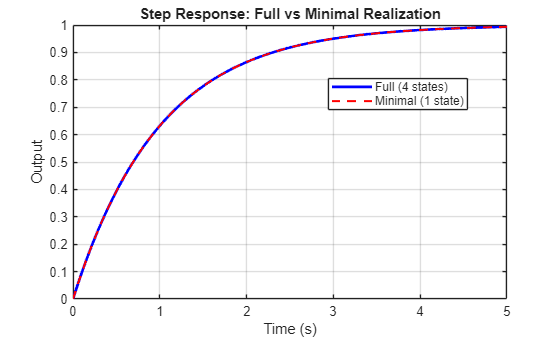


% fprintf('Transfer function (original):\n');
% disp(tf(num_full, den_full));
% 
% fprintf('Transfer function (minimal):\n');
% disp(tf(num_min, den_min));

% Verify step responses are identical
figure('Name', 'Kalman Decomposition - Step Response Comparison');
t = 0:0.01:5;
[y_full, ~] = step(sys_full, t);
[y_min, ~] = step(sys_min, t);

plot(t, y_full, 'b-', 'LineWidth', 2, 'DisplayName', 'Full (4 states)');
hold on;
plot(t, y_min, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Minimal (1 state)');
grid on;
xlabel('Time (s)');
ylabel('Output');
title('Step Response: Full vs Minimal Realization');
legend('Location', 'best');


fprintf('Step response difference (max error): %.2e\n\n', max(abs(y_full - y_min)));

Step response difference (max error): 0.00e+00



## Section 3.6: Canonical Forms

**Concept Overview**

Canonical forms are standard state-space representations:

- **Controllable canonical form** - easy controller design

- **Observable canonical form** - easy observer design

- **Modal (diagonal) canonical form** - decoupled dynamics

Function: `canon(sys, 'type')`

% Original system
A_orig = [0 1; -6 -5];
B_orig = [0; 1];
C_orig = [1 0];
D_orig = 0;

sys_orig = ss(A_orig, B_orig, C_orig, D_orig);

fprintf('Original system:\n');

Original system:


fprintf('A =\n'); disp(A_orig);

A =
     0     1
    -6    -5



fprintf('B =\n'); disp(B_orig);

B =
     0
     1



Controllable canonical form (companion form)

[sys_ctrl, T_ctrl] = canon(sys_orig,'companion');

fprintf('Controllable Canonical Form:\n');

Controllable Canonical Form:


fprintf('A_c =\n'); disp(sys_ctrl.A);

A_c =
     0    -6
     1    -5



fprintf('B_c =\n'); disp(sys_ctrl.B);

B_c =
     1
     0



fprintf('Transformation matrix T:\n'); disp(T_ctrl);

Transformation matrix T:
     5     1
     1     0



**Observable canonical form**

Observable companion via dual + map back

% 1) Dual system
sys_dual = ss(A_orig.', C_orig.', B_orig.', D_orig);

% 2) Put the dual in controllable companion
[sys_dual_c, T_dual] = canon(sys_dual, 'companion');

% 3) Map back to observable companion of the original
A_o = sys_dual_c.A.';     % transpose back
B_o = sys_dual_c.C.';     % note the swap
C_o = sys_dual_c.B.';
D_o = D_orig;

% 4) Transformation for the original system (so that T_o^{-1} A T_o = A_o)
T_o = inv(T_dual.');      % T_o = (T_dual^{-1})^T

%% Display
fprintf('Observable Canonical Form:\n');

Observable Canonical Form:


disp('A_o ='); disp(A_o);

A_o =
     0     1
    -6    -5



disp('B_o ='); disp(B_o);

B_o =
     0
     1



disp('C_o ='); disp(C_o);

C_o =
     1     0



disp('Transformation matrix T_o ='); disp(T_o);

Transformation matrix T_o =
     1     0
     0     1




%% Verify
tol = 1e-10;
ok = norm(T_o\A_orig*T_o - A_o, 'fro') < tol && ...
     norm(T_o\B_orig - B_o)     < tol   && ...
     norm(C_orig*T_o - C_o)     < tol;
fprintf('Verification passed: %d\n', ok);

Verification passed: 1


Modal (diagonal) form

[sys_modal, T_modal] = canon(sys_orig, 'modal');

fprintf('\nModal Canonical Form:\n');


Modal Canonical Form:


fprintf('A_m (diagonal with eigenvalues):\n'); 

A_m (diagonal with eigenvalues):


disp(sys_modal.A);

   -2.0000         0
         0   -3.0000



fprintf('B_m =\n'); disp(sys_modal.B);

B_m =
    2.8284
    3.6056



Verify eigenvalues are preserved

fprintf('Eigenvalues (original): ');

Eigenvalues (original): 

fprintf('%.4f ', eig(A_orig));

-2.0000 -3.0000 

fprintf('\n');
fprintf('Eigenvalues (modal): ');

Eigenvalues (modal): 

fprintf('%.4f ', eig(sys_modal.A));

-3.0000 -2.0000 

fprintf('\n\n');

## Section 3.7: State-Space Transformations

**Mathematical Background**

Similarity transformation: $\bar{A} = T^{-1}AT$, $\bar{B} = T^{-1}B$, $\bar{C} = CT$

Transfer function is invariant: $C(sI-A)^{-1}B = \bar{C}(sI-\bar{A})^{-1}\bar{B}$

A_tf = [0 1; -2 -3];
B_tf = [0; 1];
C_tf = [1 0];
D_tf = 0;

% Custom transformation matrix
T = [1 2; 0 1];

fprintf('Original system:\n');

Original system:


fprintf('A =\n'); disp(A_tf);

A =
     0     1
    -2    -3



fprintf('B =\n'); disp(B_tf);

B =
     0
     1



fprintf('C =\n'); disp(C_tf);

C =
     1     0




fprintf('\nTransformation matrix T:\n');


Transformation matrix T:


disp(T);

     1     2
     0     1




% Transform using ss2ss
sys_original = ss(A_tf, B_tf, C_tf, D_tf);
sys_transformed = ss2ss(sys_original, T); % ss2ss performs the similarity transformation

fprintf('Transformed system (using ss2ss):\n');

Transformed system (using ss2ss):


fprintf('A_new =\n'); disp(sys_transformed.A);

A_new =
    -4     3
    -2     1



fprintf('B_new =\n'); disp(sys_transformed.B);

B_new =
     2
     1



fprintf('C_new =\n'); disp(sys_transformed.C);

C_new =
     1    -2




% Manual transformation for verification
A_new_manual = T * A_tf / T;
B_new_manual = T * B_tf;
C_new_manual = C_tf / T;

fprintf('\nManual transformation verification:\n');


Manual transformation verification:


fprintf('A_new (manual) =\n'); disp(A_new_manual);

A_new (manual) =
    -4     3
    -2     1



fprintf('Error in A: %.2e\n', norm(sys_transformed.A - A_new_manual));

Error in A: 0.00e+00



% Verify transfer functions are identical
fprintf('\nTransfer function (original):\n');


Transfer function (original):


tf_orig = tf(sys_original)


tf_orig =
 
        1
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.


fprintf('Transfer function (transformed):\n');

Transfer function (transformed):


tf_trans = tf(sys_transformed)


tf_trans =
 
        1
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.


## Section 3.8: Balanced Realization

**Concept Overview**

Balanced realization transforms system so that:

- Controllability gramian = Observability gramian = Σ (diagonal)

- Diagonal elements (Hankel singular values) indicate state importance

- Enables systematic model reduction

Function: `balreal(sys)`

% Create a higher-order system
A_bal = [-1  0   0.5  0;
          0  -2  0    0.3;
          0  0   -5   0;
          0  0   0    -10];
      
B_bal = [1; 0.5; 0.2; 0.1];
C_bal = [1 1 0.5 0.1];
D_bal = 0;

sys_unbal = ss(A_bal, B_bal, C_bal, D_bal);

fprintf('Original system (4 states):\n');

Original system (4 states):



% Compute gramians before balancing
Wc_before = gram(sys_unbal, 'c');
Wo_before = gram(sys_unbal, 'o');

fprintf('Controllability gramian eigenvalues:\n');

Controllability gramian eigenvalues:


disp(sort(eig(Wc_before), 'descend'));

    0.5759
    0.0081
    0.0004
    0.0000




fprintf('Observability gramian eigenvalues:\n');

Observability gramian eigenvalues:


disp(sort(eig(Wo_before), 'descend'));

    0.7656
    0.0218
    0.0010
    0.0000




% Balanced realization
[sys_bal, g, T_bal] = balreal(sys_unbal);

fprintf('\nHankel singular values (importance of each state):\n');


Hankel singular values (importance of each state):


disp(g);

    0.6317
    0.0139
    0.0006
    0.0000




fprintf('Balanced system:\n');

Balanced system:


sys_bal


sys_bal =
 
  A = 
            x1       x2       x3       x4
   x1   -1.216  -0.4986  -0.1482  0.02552
   x2  -0.4986   -2.419   -1.353   0.2421
   x3  -0.1482   -1.353   -5.013    1.698
   x4  0.02552   0.2421    1.698   -9.352
 
  B = 
             u1
   x1     -1.24
   x2   -0.2597
   x3  -0.07558
   x4     0.013
 
  C = 
             x1        x2        x3        x4
   y1     -1.24   -0.2597  -0.07558     0.013
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



% Gramians of balanced system should be equal and diagonal
Wc_after = gram(sys_bal, 'c');
Wo_after = gram(sys_bal, 'o');

fprintf('Controllability gramian (balanced):\n');

Controllability gramian (balanced):


disp(Wc_after);

    0.6317   -0.0000    0.0000    0.0000
   -0.0000    0.0139    0.0000    0.0000
    0.0000    0.0000    0.0006    0.0000
    0.0000    0.0000    0.0000    0.0000




fprintf('Observability gramian (balanced):\n');

Observability gramian (balanced):


disp(Wo_after);

    0.6317    0.0000   -0.0000   -0.0000
    0.0000    0.0139   -0.0000    0.0000
   -0.0000   -0.0000    0.0006    0.0000
   -0.0000    0.0000    0.0000    0.0000




fprintf('Difference between gramians: %.2e\n', norm(Wc_after - Wo_after));

Difference between gramians: 7.36e-15


Model reduction: keep only significant states

If a Hankel singular value is very small, that state contributes little

threshold = 0.1 * g(1);  % Keep states with σ > 10% of largest
n_keep = sum(g > threshold);

fprintf('\nModel reduction threshold: %.4f\n', threshold);


Model reduction threshold: 0.0632


fprintf('States to keep: %d out of %d\n', n_keep, length(g));

States to keep: 1 out of 4



% Extract reduced model
A_red = sys_bal.A(1:n_keep, 1:n_keep);
B_red = sys_bal.B(1:n_keep, :);
C_red = sys_bal.C(:, 1:n_keep);
D_red = sys_bal.D;

sys_reduced = ss(A_red, B_red, C_red, D_red);

fprintf('\nReduced system:\n');


Reduced system:


disp(sys_reduced);

  ss with properties:

                A: -1.2162
                B: -1.2396
                C: -1.2396
                D: 0
                E: []
          Offsets: []
           Scaled: 0
        StateName: {''}
        StatePath: {''}
        StateUnit: {''}
    InternalDelay: [0×1 double]
       InputDelay: 0
      OutputDelay: 0
        InputName: {''}
        InputUnit: {''}
       InputGroup: [1×1 struct]
       OutputName: {''}
       OutputUnit: {''}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
               Ts: 0
         TimeUnit: 'seconds'
     SamplingGrid: [1×1 struct]



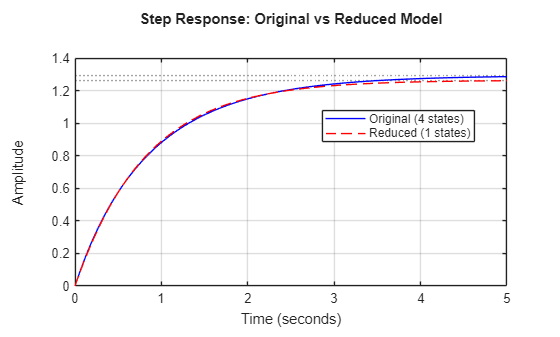


% Compare step responses
figure('Name', 'Balanced Realization - Model Reduction');
step(sys_unbal, 'b-', sys_reduced, 'r--', 5);
grid on;
legend('Original (4 states)', sprintf('Reduced (%d states)', n_keep), ...
    'Location', 'best');
title('Step Response: Original vs Reduced Model');

using a task:

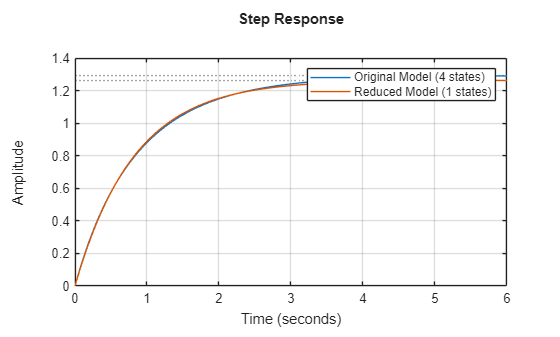

%% Reduce LTI model order using balanced truncation
 
% Compute reduced-order approximation
R = reducespec(sys_unbal,'balanced');
% Compute MOR data once
R = process(R);
% Get reduced-order model
sysReduced = getrom(R,Order=1,Method='truncate');
 
% Create comparison plot
f = figure();
h = stepplot(f,sys_unbal,sysReduced);
legend(h,['Original Model (',mat2str(order(sys_unbal)),' states)'],...
         ['Reduced Model (',mat2str(order(sysReduced)),' states)']);
h.AxesStyle.GridVisible = true;

 
 
% Remove temporary variables from Workspace
clear R f h

## Section 3.9: Minimal Realization from Transfer Function

**Concept Overview**

Given a transfer function, find the minimal state-space realization:

- Convert to state-space: `tf2ss`

- Remove uncontrollable/unobservable modes: `minreal in which` eliminates uncontrollable or unobservable state in state-space models, or cancels pole-zero pairs in transfer functions or zero-pole-gain models.

% Transfer function with pole-zero cancellation

Goal transfer function: $\frac{\left(s+1\right)\left(s+2\right)}{\left(s+1\right)\left(s+3\right)\left(s+4\right)}\longrightarrow \frac{\left(s+2\right)}{\left(s+3\right)\left(s+4\right)}$

num_cancel = conv([1 1], [1 2]);  % (s+1)(s+2)
den_cancel = conv([1 1], conv([1 3], [1 4]));  % (s+1)(s+3)(s+4)

fprintf('Transfer function with cancellation:\n');

Transfer function with cancellation:


fprintf('Numerator (zeros at s=-1,-2): ');

Numerator (zeros at s=-1,-2): 

fprintf('%.0f ', num_cancel);

1 3 2 

fprintf('\n');
fprintf('Denominator (poles at s=-1,-3,-4): ');

Denominator (poles at s=-1,-3,-4): 

fprintf('%.0f ', den_cancel);

1 8 19 12 

fprintf('\n\n');

fprintf('G(s) =\n');

G(s) =


tf_cancel = tf(num_cancel, den_cancel)


tf_cancel =
 
       s^2 + 3 s + 2
  -----------------------
  s^3 + 8 s^2 + 19 s + 12
 
Continuous-time transfer function.



% Convert to state-space (may include cancelling mode)
sys_ss_cancel = ss(tf_cancel);

fprintf('State-space realization (before minreal): %d states\n', size(sys_ss_cancel.A, 1));

State-space realization (before minreal): 3 states


Minimal realization

sys_min_cancel = minreal(sys_ss_cancel);

1 state removed.



fprintf('Minimal realization: %d states\n', size(sys_min_cancel.A, 1));

Minimal realization: 2 states



fprintf('\nMinimal state-space:\n');


Minimal state-space:


fprintf('A =\n'); disp(sys_min_cancel.A);

A =
   -1.5067   -0.4533
    8.2133   -5.4933



fprintf('B =\n'); disp(sys_min_cancel.B);

B =
    0.8889
   -1.7778




fprintf('Poles (eigenvalues of A): ');

Poles (eigenvalues of A): 

fprintf('%.4f ', eig(sys_min_cancel.A));

-3.0000 -4.0000 

fprintf('\n');
fprintf('(Cancelled pole at s=-1 removed)\n\n');

(Cancelled pole at s=-1 removed)



fprintf('Simplified transfer function after minreal:\n');

Simplified transfer function after minreal:


tf_min_cancel = tf(sys_min_cancel)


tf_min_cancel =
 
      s + 2
  --------------
  s^2 + 7 s + 12
 
Continuous-time transfer function.


## Section 3.10: Summary and Key Takeaways

**Key Concepts Covered:**

- Controllability: rank test, PBH test, gramians

- Observability: rank test, PBH test, gramians

- Kalman decomposition and minimal realization

- Canonical forms: controllable, observable, modal

- State-space transformations and similarity

- Balanced realization for model reduction

- Minimal realization from transfer functions

**MATLAB Functions Mastered:**

`ctrb`, `obsv`, `rank`, `gram`, `canon`, `ss2ss`, `minreal`, `balreal`, `ss2tf`, `tf2ss`, `ssdata`

**Structural Property Tests:**

- Rank test: $rank(\mathcal{C}) = n$ or $rank(\mathcal{O}) = n$

- PBH test: $rank([\lambda I-A, B]) = n$ for all eigenvalues

- Gramian test: $W_c > 0$ or $W_o > 0$

**Next Steps:**

These structural properties enable:

- Stability analysis and state feedback design (Season 4)

- Observer design (requires observability) (Season 5)

- System simplification and model reduction